# 정속주행 제어 : 시스템 해석 (한글판)

원문 : Control Tutorials for MATLAB and Simulink — Cruise Control: System Analysis 한글 정리 : 제어시스템설계 · 충남대학교 자율운항시스템공학과

자동차의 **정속주행(크루즈 컨트롤)** 은 제어 문제 중 가장 단순한 축에 듭니다. 그래서 처음 배우기에 좋습니다.

이 문서에서 하는 것

- 아주 단순한 1차 모델을 세운다

- 사양을 적는다

- 제어기 없이 넣어 보고 **왜 부족한지** 확인한다

clc; close all;
s = tf('s');

## 1. 모델 세우기

차를 질량 $m$ 인 덩어리로 보고, 엔진이 미는 힘 $u$ 와 공기저항·마찰이 잡아당기는 힘 $b\,v$ 만 생각합니다.

뉴턴의 제2법칙을 쓰면


$$m\,\frac{dv}{dt} + b\,v = u$$


미분이 한 번뿐이므로 **1차 시스템**입니다. 에너지를 저장하는 곳이 **질량 하나**뿐이기 때문입니다.

라플라스 변환하면 (초기조건 $0$)


$$m\,s\,V(s) + b\,V(s) = U(s) \quad \Rightarrow \quad P(s) = \frac{V(s)}{U(s)} = \frac{1}{m s + b} \qquad \left[\frac{\mathrm{m/s}}{\mathrm{N}}\right]$$


m = 1000;      % [kg]  차 질량
b = 50;        % [N s/m]  감쇠 계수
u0 = 500;      % [N]  엔진이 미는 힘

P_cruise = 1/(m*s + b);

fprintf('=== 정속주행 모델 ===\n');
fprintf('  m = %d kg,  b = %d N s/m\n\n', m, b);
P_cruise
fprintf('  극점    : %.4f\n', pole(P_cruise));
fprintf('  시정수  : %.1f s   (= m/b)\n', m/b);
fprintf('  DC 이득 : %.4f  (1 N 을 계속 밀면 %.3f m/s)\n\n', ...
        dcgain(P_cruise), dcgain(P_cruise));

## 2. 설계 사양

$500\,\mathrm{N}$ 의 힘을 계단으로 넣었을 때 요구는 이렇습니다.

- 상승시간 $5$ 초 미만

- 오버슈트 $10\%$ 미만

- 정상상태 오차 $2\%$ 미만

목표 속도는 $10\,\mathrm{m/s}$ 입니다.

rise_spec = 5;  os_spec = 10;  ess_spec = 2;   % [s], [%], [%]
v_target  = 10;                                 % [m/s]

## 3. 개루프 응답 — 제어기 없이

제어기 없이 $500\,\mathrm{N}$ 을 그냥 넣으면 어떻게 되는지 봅니다.

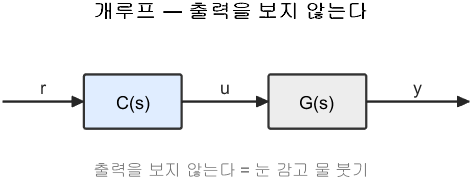

개루프 — 출력을 보지 않는다

t = (0:0.1:120)';
y = u0 * step(P_cruise, t);
info = stepinfo(u0*P_cruise);

figure;
plot(t, y, 'LineWidth', 2.5); hold on;
yline(v_target, 'k--', 'LineWidth', 1.5);
grid on; xlabel('시간 [s]'); ylabel('속도 [m s^{-1}]');
legend('개루프 응답', '목표 10 m/s', 'Location','southeast');
title('제어기 없이 500 N 을 넣으면');

fprintf('=== 개루프 응답 ===\n');
fprintf('  도달 속도  %.2f m/s   (목표 %.0f)\n', y(end), v_target);
fprintf('  상승시간   %.1f s      (요구 %d s 미만)\n', info.RiseTime, rise_spec);
fprintf('  오버슈트   %.1f %%      (요구 %d %% 미만)\n', info.Overshoot, os_spec);
fprintf('  정상상태 오차 %.1f %%\n\n', 100*abs(y(end)-v_target)/v_target);

결과를 읽어 보면

- 최종 속도는 $10\,\mathrm{m/s}$ 로 **맞습니다.** 운 좋게 $u_0/b = 500/50 = 10$ 이 되도록 힘을 골랐기 때문입니다

- 오버슈트는 $0\%$ 입니다. 1차 시스템이라 진동할 방법이 없습니다

- 그런데 상승시간이 $40$** 초가 넘습니다.** 사양은 $5$ 초입니다

즉 **너무 느립니다.** 이것이 제어기가 필요한 이유입니다.

## 4. 왜 느린가 — 시정수로 보면

1차 시스템의 성격은 시정수 하나로 정해집니다.


$$\tau = \frac{m}{b} = \frac{1000}{50} = 20\,\mathrm{s}$$


그러면 이렇게 예측됩니다.

- 상승시간 $\approx 2.2\tau = 44$ 초

- 정착시간 $\approx 4\tau = 80$ 초

빠르게 하려면 $\tau$ 를 줄여야 하는데, $m$ 과 $b$ 는 차의 성질이라 못 바꿉니다. **바꿀 수 있는 것은 제어기뿐입니다.**

tau = m/b;
fprintf('=== 1차 공식으로 예측 ===\n');
fprintf('  tau = m/b = %.0f s\n', tau);
fprintf('  예측 상승시간 2.2*tau = %.1f s   (실측 %.1f s)\n', 2.2*tau, info.RiseTime);
fprintf('  예측 정착시간 4*tau   = %.1f s   (실측 %.1f s)\n\n', 4*tau, info.SettlingTime);

## 5. 비례제어를 붙여 보면

이제 출력을 보고 고치는 구조로 바꿉니다.

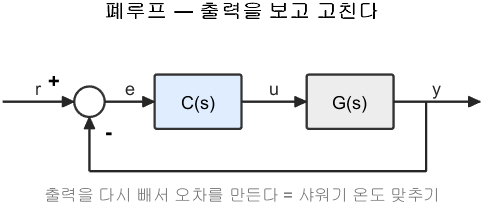

폐루프 — 출력을 보고 고친다

비례제어 $C(s) = K_p$ 를 붙이면 폐루프는 이렇게 됩니다.


$$T(s) = \frac{K_p\,P}{1 + K_p\,P} = \frac{K_p}{m s + b + K_p}$$


여전히 1차인데 시정수가 바뀌었습니다.


$$\tau_{cl} = \frac{m}{b + K_p}$$


$K_p$** 를 키우면 시정수가 작아집니다.** 즉 빨라집니다. 그리고 정상상태 이득은 $\frac{K_p}{b + K_p}$ 이므로 오차는


$$e_{ss} = 1 - \frac{K_p}{b+K_p} = \frac{b}{b+K_p}$$


역시 $K_p$ 를 키우면 작아집니다.

t2 = (0:0.05:30)';
figure;
hold on; grid on;
fprintf('=== 비례제어 ===\n');
fprintf('     Kp    폐루프 시정수[s]  상승시간[s]  정상상태 오차[%%]\n');
fprintf('  ------  ----------------  -----------  ----------------\n');
for Kp = [100 500 1000 2000]
    T = feedback(Kp*P_cruise, 1);
    ii = stepinfo(T);
    plot(t2, v_target*step(T, t2), 'LineWidth', 2, 'DisplayName', sprintf('K_p = %d', Kp));
    fprintf('  %6d  %16.2f  %11.2f  %16.2f\n', ...
            Kp, m/(b+Kp), ii.RiseTime, 100*(1-dcgain(T)));
end
yline(v_target, 'k--', 'HandleVisibility','off');
xlabel('시간 [s]'); ylabel('속도 [m s^{-1}]');
legend('Location','southeast');
title('비례이득을 키우면 빨라지고 정확해진다');
fprintf('\n');

1차 시스템이라 **이득을 키워도 진동하지 않습니다.** 극점이 실수 하나뿐이라 진동할 방법이 없기 때문입니다.

그러면 이득을 무한히 키우면 되겠네요? 그렇지 않습니다.

- 제어입력 $u = K_p\,e$ 가 그만큼 커진다. 엔진이 낼 수 있는 힘에는 한계가 있다

- 실제 차에는 모델에 없는 지연과 고차 성분이 있다. 그것들이 진동을 만든다

- 센서 잡음도 $K_p$ 배로 증폭된다

**모델이 단순하다고 이득을 마음대로 키워도 되는 것은 아닙니다.**

fprintf('=== 필요한 엔진 힘 ===\n');
for Kp = [100 500 1000 2000]
    [~, ~, um] = ctrl_input(Kp, P_cruise, (0:0.05:30)');
    fprintf('  Kp = %4d : 최대 제어입력 %8.0f N  (목표 10 m/s 기준 %.0f N)\n', ...
            Kp, um*v_target, um*v_target);
end
fprintf('  --> 이득을 키울수록 엔진이 더 세게 밀어야 합니다.\n\n');

## 6. 정리

- 정속주행은 **1차 시스템**이다. 에너지를 저장하는 곳이 질량 하나뿐이다

- 1차 시스템은 시정수 $\tau = m/b$ 하나로 전부 설명된다

- 개루프로는 최종 속도는 맞출 수 있지만 **너무 느리다**

- 비례제어를 붙이면 시정수가 $\frac{m}{b+K_p}$ 로 줄어 빨라지고 오차도 준다

- 1차라 진동은 없지만, **제어입력·잡음·모델 오차** 때문에 무한정 키울 수는 없다

이 과목의 1, 2, 4 주차 내용과 그대로 이어집니다.